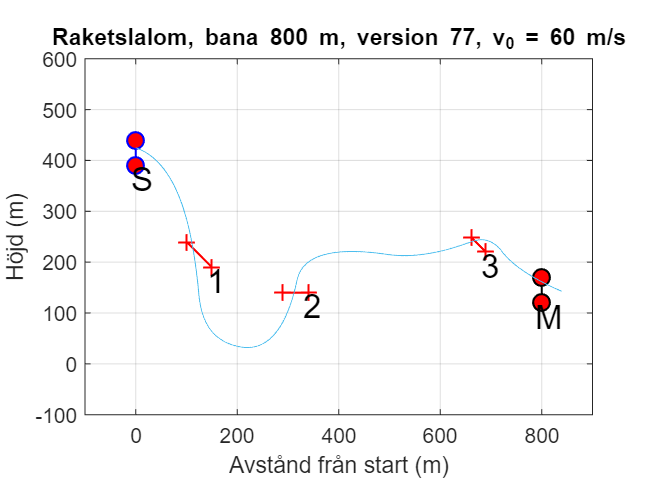

clear
clf
format short
%format long
load bana800-77.mat
plotTrack(portx, porty, ver, v1);
ylim([-100 600])
xlim([-100 900])

yStartSpeed = -20; 
xStartSpeed = sqrt(v1^2 - yStartSpeed^2);

tspan = [0, 24]; % inte [0, 800]
xybv = [0, xStartSpeed, 425, yStartSpeed]; % 4 inputs? x, x', y, y'
n = 1000;
%[t1,y_ode] = ode45(@mp3Funk,tspan,xybv);
[t1,yRk4] = minRK4(@mp3Funk,tspan,xybv, n);
%x = y_ode(:,1);
%y = y_ode(:,3);
hold on
plot(yRk4(:,1), yRk4(:,3))

%plot(y(:,1), y(:,3))



% if t < 5
%     theta = 2*pi/4;
% elseif t < 8
%     theta = 5*pi/4;
% elseif t < 13
%     theta = 3*pi/2;
% elseif t < 17
%     theta = pi;
% elseif t < 20
%     theta = 5*pi/4;
% elseif t < 21.5
%     theta = pi/2;
% elseif t < 25 
%     theta = pi;
% else 
%     theta = 3*pi/2;
% end

clf;

angle_time = [0 5 5 8 8 13 13 17 17 20 20 21.5 21.5 24]

angle_time =          0    5.0000    5.0000    8.0000    8.0000   13.0000   13.0000   17.0000   17.0000   20.0000   20.0000   21.5000   21.5000   24.0000


angle_values = [pi/2 pi/2 5*pi/4 5*pi/4 3*pi/2 3*pi/2 pi pi 5*pi/4 5*pi/4 pi/2 pi/2 pi pi]

angle_values =     1.5708    1.5708    3.9270    3.9270    4.7124    4.7124    3.1416    3.1416    3.9270    3.9270    1.5708    1.5708    3.1416    3.1416


angle_values = rad2deg(angle_values)

angle_values =     90    90   225   225   270   270   180   180   225   225    90    90   180   180


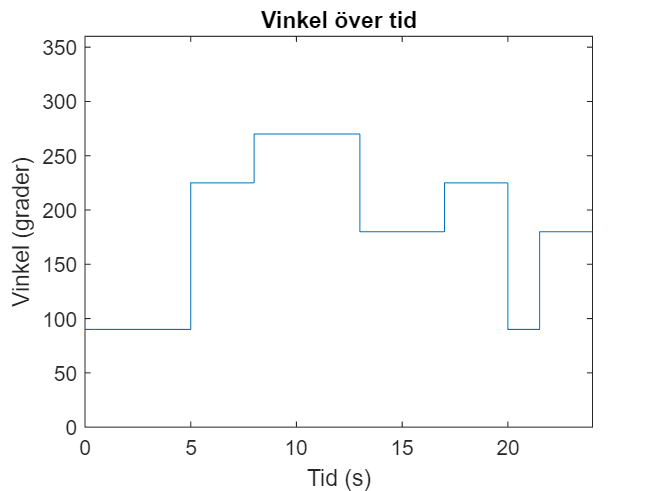

plot(angle_time, angle_values)
ylim([0 360])
xlim([0 24])
xlabel('Tid (s)')
ylabel('Vinkel (grader)')
title('Vinkel över tid')

clf
speeeed = sqrt(yRk4(:,2).^2 + yRk4(:,4).^2)

speeeed =    60.0000
   59.7460
   59.5066
   59.2815
   59.0703
   58.8728
   58.6887
   58.5175
   58.3591
   58.2130


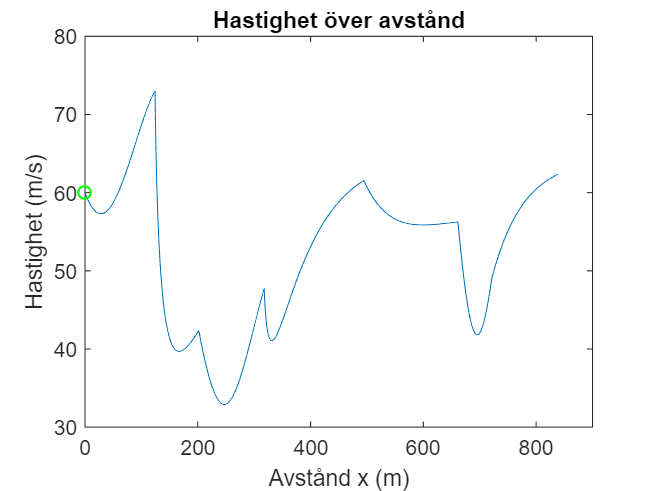

plot(yRk4(:,1), speeeed)
hold on
plot(0, 60, 'go', LineWidth=1)
%plot(0, 60, 'go', LineWidth=2)

ylim([30 80])
xlim([0 900])
xlabel('Avstånd x (m)')
ylabel('Hastighet (m/s)')
title('Hastighet över avstånd')

clear
clf
x = linspace(1,800,800)
% 400 + −2,18x + 4,89×10^−03x^2 + −2,05×10^−06x^3 + −1,46×10^−09x^4
y = 400 - 2.18 * x + 4.89 * 10^-3 * x.^2 - 2.05 * 10^-6 * x.^3 - 1.46*10^-9 * x.^4
plot(x, y, '--r')
hold off
% deriv
% -2.18 + 0.00978 x - 6.15×10^-6 x.^2 - 5.84×10^-9 x.^3
yderiv = -2.18 + 0.00978 * x - 6.15 * 10^-6 * x.^2 - 5.84 * 10^-9 * x.^3
plot(x, yderiv, '--g')
hold on
